# Codigos de Proyecto 

- Sección: 2

- N° de grupo: 9

- Titulo del Proyecto: Modelación numérica de un ecosistema depredador-presa mediante teoría difusa y respuesta funcional Holling tipo II

- Integrante 1 (líder):  Valdiviezo Ortiz, José Rodrigo 100%

- Integrante 2: Huertos Ochoa, Rodrigo Franco  100%

- Integrante 3: Cepeda Cavero, Juan Pablo  100%

- Integrante 4: Anco Ito, Rodrigo de Santa Maria  100%

- Integrante 5: Mendoza Aguilar, Ernesto Yen   100%

**Observación:** 

- No olvidar añadir el porcentaje de participación.

- Incluir comentarios relevantes para entender el codigo, tener en cuenta que comentarios de IA anularan la entrega

- El codgio debe de tener una identacion adecuada para facilitar su lectura

- El codigo debe der replicable en cualquier computadora (Uso adecuado de semillas para funciones)

- Las funciones principales deben de ir en la parte inferior de este archivo

- Titulos de los codigos deben reflejar su funcionalidad

## Código 1: Parámetros y Escenario Base

clear; clc; close all;

%Guaradmos lo parámetros de la tabla 1.
a = 0.5; b = 0.254; K = 1000; A = 500; c = 0.125; d = 0.325;
E = 0; p1 = 1; p2 = 1;
X0 = [1100; 900];
T = 600; h = 0.1;

%Se agrupa en una structura par que permite pasarlo a una función.
par = struct('a',a,'b',b,'K',K,'A',A,'c',c,'d',d,'E',E,'p1',p1,'p2',p2);

%Se calcula el punto de equilibrio de presas(xe) y depredadores(ye) usando
%las funciones analíticas.
xe = A*c/(d-c);
ye = a*(A+xe)/b*(1 - xe/K);

##  Código 2: Simulación del caso base con RK5

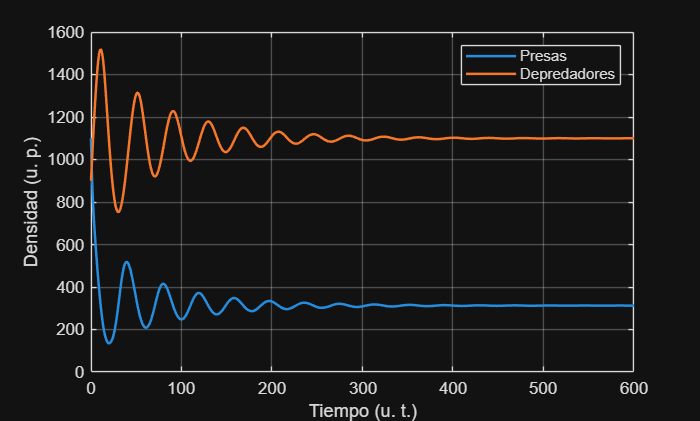

%Ya definimos los parámetros, simulamos el caso base del modelo con RK5.
f = @(X) modelo(X, par);
[t, X] = rk5_cashkarp(f, T, X0, h);

figure;
plot(t, X(1,:), 'LineWidth', 1.5); hold on;
plot(t, X(2,:), 'LineWidth', 1.5);
xlabel('Tiempo (u. t.)'); ylabel('Densidad (u. p.)');
legend('Presas', 'Depredadores'); grid on;
% Se dibuja el plano de fases con condiciones inicales.
CI = [1100 200 800 300; 900 500 1400 1100];
figure; hold on;
for i = 1:size(CI,2)
    [~, Xi] = rk5_cashkarp(f, T, CI(:,i), h);
    plot(Xi(1,:), Xi(2,:));

end
plot(xe, ye, 'k*'); % * es equilibrio
xlabel('Presas (u. p.)'); ylabel('Depredadores (u. p.)'); grid on;

## Código 3: Trayectorias con distintos esfuerzos de cosecha (Figura 1)

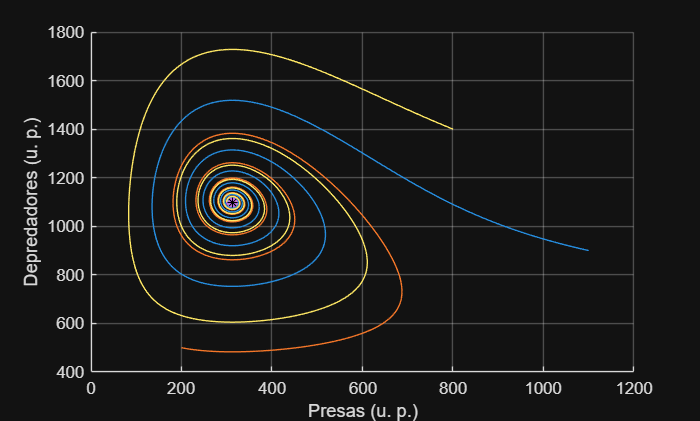

% Simula con 4 valores de esfuerzo de cosecha. (figura 1) 
esfuerzos = [0 0.05 0.08 0.6];
figure;
for k = 1:numel(esfuerzos)
    par.E = esfuerzos(k);
    fE = @(X) modelo(X, par);

    [tE, XE] = rk5_cashkarp(fE, 200, X0, h);
    subplot(1,2,1); plot(tE, XE(1,:)); hold on;
    subplot(1,2,2); plot(tE, XE(2,:)); hold on;
end
subplot(1,2,1); title('Presas'); xlabel('Tiempo (u. t.)'); ylabel('Densidad (u. p.)');
subplot(1,2,2); title('Depredadores'); xlabel('Tiempo (u. t.)');
legend('E=0','E=0.05','E=0.08','E=0.6');
par.E = 0;


## Código 4: Estudio de convergencia por tamaño de paso

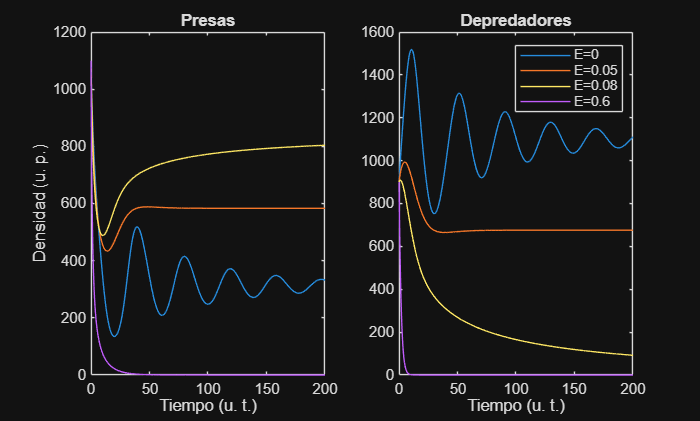

% genera la solucion con el href muy pequeño, asi podemos medir errores.
f = @(X) modelo(X, par);
hRef = 0.00625;
[~, Xref] = rk5_cashkarp(f, T, X0, hRef);


hs = [0.4 0.2 0.1 0.05];
errX = zeros(1, numel(hs));
errY = zeros(1, numel(hs));
for i = 1:numel(hs)
    [~, Xh] = rk5_cashkarp(f, T, X0, hs(i));

    %compara el xref con los valores temporales de la malla gruesa
    paso = round(hs(i)/hRef); % El salto que debe hacer para encontrar los instantes con la malla gruesa
    Xcmp = Xref(:, 1:paso:end);
    errX(i) = max(abs(Xh(1,:) - Xcmp(1,:)));
    errY(i) = max(abs(Xh(2,:) - Xcmp(2,:)));
end

%log2 del cociente de errores debe dar cerca de 5.Con eso calcula el orden
%estimado con el cociente de los errores.
orden = [NaN, log2(errX(1:end-1)./errX(2:end))];
evaluaciones = 6*round(T./hs);

tabla = table(hs', errX', errY', orden', evaluaciones', ...
    'VariableNames', {'h','ErrorX','ErrorY','Orden','EvalF'});
disp(tabla);

## Código 5: Comparación con RK4 clásico

%Se utliiza el mismo procedimiento para poder RK4, con eso comparamos para
%saber la mayor precisión de con el RK5
hs4 = [0.4 0.2 0.1 0.05];
err4 = zeros(1, numel(hs4));
for i = 1:numel(hs4)
    [~, X4] = rk4_clasico(f, T, X0, hs4(i));
    paso = round(hs4(i)/hRef);
    Xcmp = Xref(:, 1:paso:end);

     h        ErrorX        ErrorY      Orden     EvalF
    ____    __________    __________    ______    _____

     0.4    2.5834e-06     5.111e-06       NaN     9000
     0.2    7.3552e-08    1.4188e-07    5.1344    18000
     0.1    2.2258e-09    4.1443e-09    5.0464    36000
    0.05    7.3442e-11    1.2551e-10    4.9216    72000



    err4(i) = max(max(abs(X4 - Xcmp)));
end
disp(table(hs4', err4', 'VariableNames', {'h','ErrorMaxRK4'}));

## Código 6: Chequeos de coherencia

% Comprueba que las poblaciones se mantegan positivas y se evalúa en
% [500,600] en las oscilaciones, para comprobar la estabilidad dle sistema.
[t, X] = rk5_cashkarp(f, T, X0, h);
minimos = min(X, [], 2);
ventana = t >= 500 - 1e-9;
ampX = max(X(1,ventana)) - min(X(1,ventana));
ampY = max(X(2,ventana)) - min(X(2,ventana));
fprintf('Minimos: x = %.4f, y = %.4f\n', minimos(1), minimos(2));
fprintf('Amplitudes en [500,600]: x = %.4f, y = %.4f\n', ampX, ampY);

     h      ErrorMaxRK4
    ____    ___________

     0.4     0.0010947 
     0.2    6.1607e-05 
     0.1      3.65e-06 
    0.05    2.2209e-07 



## Funciones Principales


%Evalua las ecuaciones diferenciales del sistema de depredador-presa con o
%sin cosecha
function dX = modelo(X, par)
    x = X(1); y = X(2);
    dx = par.a*x*(1 - x/par.K) - par.b*x*y/(par.A + x) - par.p1*par.E*x;
    dy = -par.c*y + par.d*x*y/(par.A + x) - par.p2*par.E*y;
    dX = [dx; dy];
end

Minimos: x = 134.9755, y = 752.5944


Amplitudes en [500,600]: x = 0.9194, y = 1.6431


%RK5
function [t, X] = rk5_cashkarp(f, T, X0, h)
    %Representa la cantidad total de pasos con el intervalo [0,T]
    N = round(T/h);
    t = (0:N)*h;

    % X es una amtriz que almacena el estado de las poblaciones, depredador
    % y presa (es decir las filas) con cada paso del tiempo (es decir, columnas, con N+1) 
    X = zeros(numel(X0), N+1);
    X(:,1) = X0;

    for n = 1:N
        Xn = X(:,n);
        
        % Se evalua desde k1 a k6 (las 6 pendientes) con distintas
        % posciones intermedias con el paso del tiempo de h.
        k1 = f(Xn);
        k2 = f(Xn + h*(1/5*k1));
        k3 = f(Xn + h*(3/40*k1 + 9/40*k2));
        k4 = f(Xn + h*(3/10*k1 - 9/10*k2 + 6/5*k3));
        k5 = f(Xn + h*(-11/54*k1 + 5/2*k2 - 70/27*k3 + 35/27*k4));
        k6 = f(Xn + h*(1631/55296*k1 + 175/512*k2 + 575/13824*k3 ...
                       + 44275/110592*k4 + 253/4096*k5));

        % Se actualiza la nueva posción de la poblacion en el timepo t + h,
        % con el promedio ponderado de k1,k2,k3,k4 (k2,k5 se les da peso 0 en la combinación final)
        X(:,n+1) = Xn + h*(37/378*k1 + 250/621*k3 + 125/594*k4 + 512/1771*k6);
    end
end

%Esto se utiliza para comparar con el RK4
function [t, X] = rk4_clasico(f, T, X0, h)
    
    %pasos a simular
    N = round(T/h);
    
    %Vector de tiempo y la misma matrix X de RK5
    t = (0:N)*h;
    X = zeros(numel(X0), N+1);
    X(:,1) = X0;
    for n = 1:N
        Xn = X(:,n);

        %Utiliza solo 4 pendientes, a diferencia de RK5 
        k1 = f(Xn);
        k2 = f(Xn + h/2*k1);
        k3 = f(Xn + h/2*k2);
        k4 = f(Xn + h*k3);

        % Utiliza la ponderacion de la regla de Simpson
        X(:,n+1) = Xn + h/6*(k1 + 2*k2 + 2*k3 + k4);
    end
end




